# KUKA KR 60

Motion planning of a KUKA 6DoF (Kuka KR 60) robot.

## Introduction

Please, refer to following link for technical data: *http://www.wtech.com.tw/public/download/manual/kuka/KR_60HA.pdf*

## 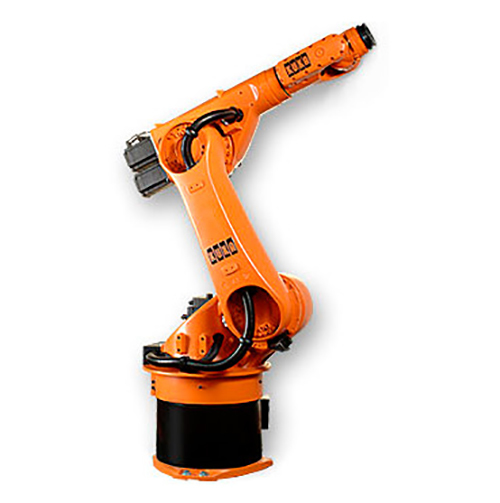    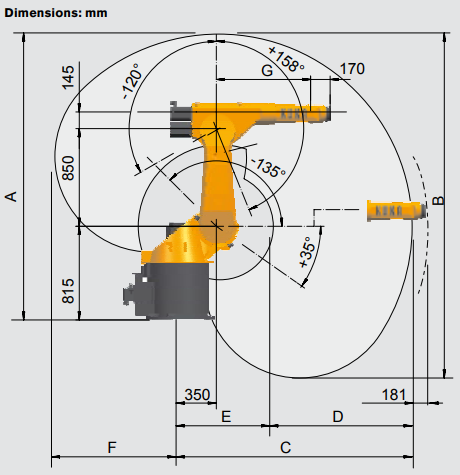

This manipulator is a 6-axiss jointed-arm kinematic system, that consists of the following components:

- Base frame

- Rotating column

- Link arm

- Arm

- Triple-axis in-line wirst

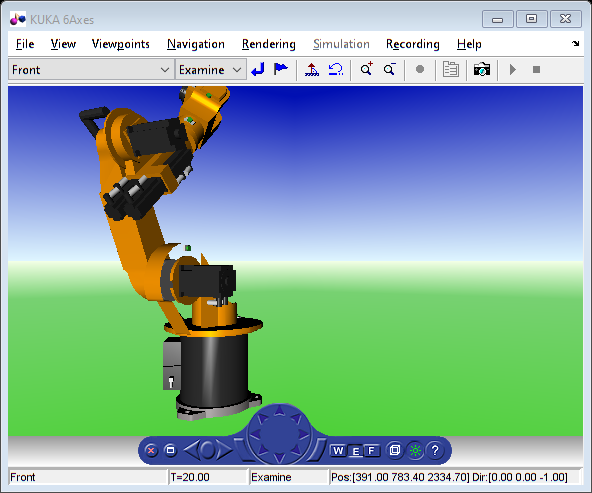

open('KukaKR6.wrl')

## Denavit-Hartenbergs parameters

Firstly, each link is assigned with a D-H coordinate frame, conform to the rules herebelow:

- The z-axis ($z_i$) is the rotation axis of each revolute joint.

- The x-axis ($x_i$) is the normal to the current z-axis ($z_i$) and the previous one ($z_{i-1}$) and must intersect the preious z-axis ($z_{i-1}$).

- The y-axis ($y_i$) is determined by the right-hand coordinate system.

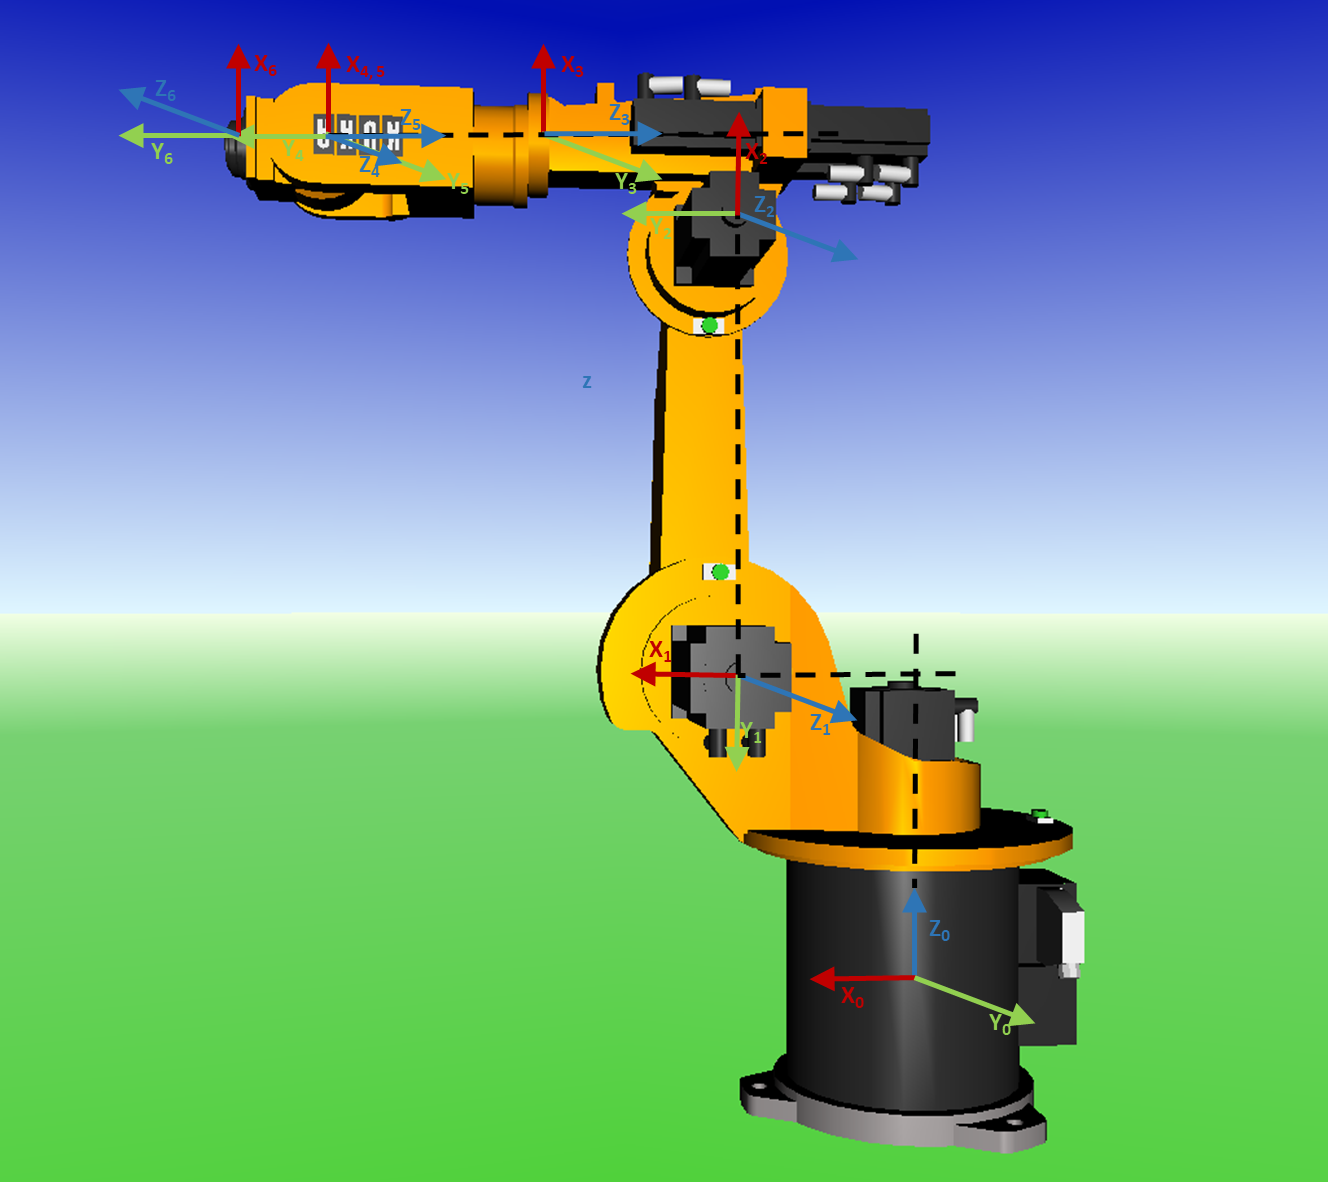

The Denavit-Hartenbergs parameters have been defined according to the DH convention, after having assigned a coordinate frame to each link of the Kuka KR 60. Hence, the D-H parameters can be computed as follow:

- $d_i$ is the distance from $x_{i-1}$ and $x_i$ along $z_i$

- $\theta_i$ (or offset) is the angle between $x_{i-1}$ and $x_i$ about $z_i$

- $a_i$ is the distance from $z_{i-1}$ to $z_i$ along $x_{i-1}$

- $a_i$ is the angle between $z_{i-1}$ to $z_i$ about $x_{i-1}$

tableFormat = true;
dhParams = loadDHParams(tableFormat);
disp(dhParams);

     d       a      alpha     offset
    ____    ___    _______    ______

     675    350    -1.5708      0   
       0    850          0      0   
       0      0     1.5708      0   
    -820      0    -1.5708      0   
       0      0     1.5708      0   
    -170      0     3.1416      0   



clear tableFormat;

## **Forward Kinematics**

The kinematics of the robot is solved using the Denavit-Hartenbergs' convention, which enables complete manipulation of the end-effector in three-dimensonal space.

The problem of the forward kinematics is to obtain the end-effector position with respect to a set of given joint angles $q_i$. The transformation from the current joint $i$ to the next is described by the matrix $A_{i+1}$:


$$A_{i+1} =\left\lbrack \begin{array}{cccc}
\cos \left(\theta \right) & -\sin \left(\theta \right)\cos \left(\alpha_{i+1} \right) & \sin \left(\theta \right)\sin \left(\alpha_{i+1} \right) & a_{i+1} \cos \left(\theta \right)\\
\sin \left(\theta \right) & \cos \left(\theta \right)\cos \left(\alpha_{i+1} \right) & -\cos \left(\theta \right)\sin \left(\alpha_{i+1} \right) & a_{i+1} \sin \left(\theta \right)\\
0 & \sin \left(\alpha_{i+1} \right) & \cos \left(\alpha_{i+1} \right) & d_{i+1} \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


The function `solve.forwardKinematics` solve this problem for a set of given joint angles `q`, by sequentially multipling each joint matrix $A_i$ ($T\;=A_1 A_2 A_3 A_4 A_5 A_6$), where $A_i$ is computed by `solver.computeT()`.

## **Inverse Kinematics**

Knowing the desired end-effector position, it is possible by meand of the inverse kinematics, to get the required joint angles to reach the target pose.

Though Newton-Raphson method is widely use to find the solution to the inverse kinematics, it doesn't guarantee the global convergence. Furthermore, also the equation solvability (target pose of end-effector and orientation) is not necessarily guardanteed. In 2009, a new technique based on the Levenberg-Marquardt was hence proposed [[1]](#M_1850E4CE). [[2]](#M_44DFAC54) used the Gauss-Newton with the Levenberg-Marquardt method as numerical optimization method, that, combined with an online learning approach, allows to reach the desired pose quicker on average. Though the online learning approach is to be considered out of the scope of this work, the numerical method is adopted.

Summarising, the Levenberg-Marquardt algorithm adaptively varies the parameter updates between the gradient descent update and the Gauss-Newton update:


$$\left(J^T \textrm{WJ}+\lambda \;I\right)h=J^T {\textrm{Wy}}_{\textrm{err}}$$


where $h$ is the parameter updated and $y_{\textrm{err}} =x_d -x\left(q\right)$

Hence: $h=\frac{J^T {\textrm{Wy}}_{\textrm{err}} }{J^T \textrm{WJ}+\lambda \;I}$.

After updating the solution $q_{\textrm{update}} =q+h^T$,  $\lambda \;$is updated:

- as the solution improves ($y_{\textrm{errNew}} <y_{\textrm{err}}$), $\lambda$ is decreased and q is updated ($q=q_{\textrm{update}}$): the Levenberg-Marquardt method approache the Gauss-Newton method, and the solutiont typically accelerated to the local minimum, as explained in [[3]](#M_48B7123D).

- if $y_{\textrm{errNew}} >y_{\textrm{err}}$, $\lambda$ is increased, and the solution diverges.

Please note, the weighting matrix is set to be simply an identity matrix.

The `solver.inverseKinematics()` implements this technique to find the desired configuration for the joint angles. The initial configuration `q` is the home configuration. A maximum number of iteration is provided to limit the computational cost at runtime: if no solution can be found in the range defined by the tolerance (default, ${10}^{-6}$), the last computed solution is returned. If the method doesn't converge to a solution, and all the calculated configurations have been rejected, the status is failed.

## **Inverse Dynamic**

Solving the inverse dynamic means calculate the joint forces and torques necessary to create the desired joint acceleration at the current joint position and velocities.

The Newton-Euler method allows to describe the dynamic motion of a rigid body system, in terms of forces and torques. In contrast with the Euler-Lagrange method (energy based) that considers the system as a whole, the NE makes use of one equation for each link, that is vualuated in a numeric form and reursive way. In particular:


$$\begin{array}{l}
\textrm{Newton}\to \;\sum_i f_i =\frac{d}{\textrm{dt}}\left({\textrm{mv}}_c \right)\\
\textrm{Euler}\to \sum_i \mu_i =\frac{d}{\textrm{dt}}\left(I\omega \right)=I\dot{\omega} +\omega \times I\omega 
\end{array}$$


The algorithm can be splitted in two steps: *forward iteration* and *backward iteration *[[4]](#M_0F3EC533). 

**The forward iteration**

Given $\theta ,\dot{\theta} ,\ddot{\theta}$, for each link (from the base to the end-effector):

- Calculate $\omega_i \;$as sum of $\omega_{i-1}$(expredsed in frame $i$) and a term due to $\dot{\theta_i }$:$\omega_i =R\left(\omega_{i-1} +z_0 \theta_i \right)$

- Calculate $\dot{\omega_i } \;$as sum of ${\dot{\omega} }_{i-1}$(expressed in frame $i$) and a term due to $\ddot{\theta_i } \;$and the velocity product term due to $\omega_i$and $\dot{\theta_i }$: ${\dot{\omega \;} }_i =R\left({\dot{\omega \;} }_{i-1} +z_0 \dot{\theta_i } \;+\omega_{i-1} \times z_0 \dot{\theta_i } \;\right)$

- Calculate $\ddot{\theta_i } \;$ as sum of a term due to ${\dot{\omega} }_i$ and a term due to $\omega_i$:$\ddot{\theta_i } \;={\dot{\omega \;} }_i \times p^* +\omega_i \times \omega_i \times p^* +R\;G$

**The backward iteration**

Given $\theta ,\dot{\theta} ,\ddot{\theta}$, for each link (from the end-effector to the base):

- Calculate $F_i$ as sum of $F_{i+1}$ and the external forces. $F_i =M_j \left(\dot{\omega_j } \times r+\omega_j \times \omega_j \times r+{\dot{\theta} }_j \right)+\;\sum_{j=i+1}^n f_j$

- Calculate $\tau_i$ as the component of $F_i$ along the joint skew axis: $\tau_j =I\dot{\omega_j } +\omega_j \times I\omega_j$ [[5]](#M_BCC0813E)

For more details about the algorithms, please refer to its implementation in `solver.inverseDynamics()`.

## Trajectory Planning

The trajectory planning problem consists in find a time series of successive joint angles that allows to achieve a task, a target configuration. 

### **Comparison between task space and joint space**

Joint-space description: the description of the motion to be made by the robot by its joint values. The motion between the two points is unpredictable.

Operational-space description: the description of the motion is in the operational space (cartesian or working space). The motion between two points is known and controllable at all time, but it is difficult to ensure that singuarities does not occur.

**Task space**

- Calculate the path from the initial point to the final point

- Assing a total time $T_{\textrm{path}}$to traverse the path

- Discretize the points in time and space

- Blend a continuous time function between these points

- Solve inverse kinematics at each step

**Joint space**

- Calculate the inverse kinematic solution from the initial point to the final point

- Assign the total time $T_{\textrm{path}}$using maximal velocities in joints

- Discretize the individual joint trajectories in time

- Blend a continuous function between these point

A small summary of the pro (OK) and contra (NO) of each space trajectory is herebelow described.


$$\matrix{
\textbf{Operational Space Trajectory} & \textbf{Joint Space Trajectory}                               \cr
\text{OK: Motion is predictable} & \text{NO: Motion not predictable} \cr
\text{OK: Collision-free path obtainable}    & \text{NO: Collision-free path not guaranteed}                             \cr
\text{NO: IK computed each time step}        & \text{OK: IK computed only once}                                     \cr
\text{NO: Unknown how to set total time}    & \text{OK: Joint and velocity constraints} \cr
\text{NO: Actuator motion not always smooth} & \text{OK: Actuator motion smooth} \cr
}$$


### Polynomial trajectory

In order to generate the trajectory, to move from the initial configuration to the target configuration, the path between the two waypoints shall be defined.

**Cubic Polynomial**

For each joint a function is required: its initial value at $t_0$ coincides with the initial configuration, while the final value at $t_F$ is the desired goal position. The four constraints used in the polynomial definition are $\theta \left(0\right)=\theta_0 ;\;\theta \left(t_F \right)=\theta_f ;\dot{\theta} \left(0\right)=0;\dot{\theta} \left(t_F \right)=0$. Hence:


$$\begin{array}{l}
\theta \left(t\right)=a_0 +a_1 t+a_2 t^2 +a_3 t^3 \\
\dot{\theta} \left(t\right)=a_1 +{2a}_2 t+{3a}_3 t^2 \\
\ddot{\theta} \left(t\right)=a_2 +{6a}_3 t
\end{array}$$


syms q0 qf v0 vf t;
c = [q0; v0; 0; 0];
T0 = [1 t; 0 1];
invTF = [3/t^2, -1/t;
    -2/t^3,  1/t^2];
c(3:4) = invTF * ([qf; vf] - T0*c(1:2));
disp(c);

$$\left(\begin{array}{c} q_{0}\\ v_{0}\\ \frac{v_{0}-\mathrm{vf}}{t}-\frac{3\,\left(q_{0}-\mathrm{qf}+t\,v_{0}\right)}{t^{2}}\\ \frac{2\,\left(q_{0}-\mathrm{qf}+t\,v_{0}\right)}{t^{3}}-\frac{v_{0}-\mathrm{vf}}{t^{2}} \end{array}\right)$$

Please, refer to the function `trajectory.cubicPolynomial `[[here](matlab:open('./srcs\matlab\+trajectory\cubicPolynomial.m'))] for the implementation.

**Quintic Polynomial**

To consider position, velocity and acceleration at the beginning and end of a path segment, a quintic polynomial is required:


$$\begin{array}{l}
\theta \left(t\right)=a_0 +a_1 t+a_2 t^2 +a_3 t^3 +a_4 t^4 +a_5 t^5 \\
\dot{\theta} \left(t\right)=a_1 +{2a}_2 t+{3a}_3 t^2 +{4a}_4 t^3 +5a_5 t^4 \\
\ddot{\theta} \left(t\right)={2a}_2 +{6a}_3 t+12a_4 t^2 +20a_5 t^3 
\end{array}$$


syms q0 qf v0 vf a0 af t;
c = [q0; v0; a0; 0; 0; 0];
T0 = [1 t t^2; 0 1 2*t; 0 0 2];
invTF = [10/t^3, -4/t^2,  1/(2*t);
    -15/t^4,  7/t^3, -1/t^2;
    6/t^5, -3/t^4,  1/(2*t^3)];
c(4:6) = invTF * ([qf; vf; af] - T0*c(1:3));
disp(c);

$$\begin{array}{l} \left(\begin{array}{c} q_{0}\\ v_{0}\\ a_{0}\\ \frac{4\,\sigma_{2}}{t^{2}}-\frac{2\,a_{0}-\mathrm{af}}{2\,t}-\frac{10\,\sigma_{1}}{t^{3}}\\ \frac{2\,a_{0}-\mathrm{af}}{t^{2}}-\frac{7\,\sigma_{2}}{t^{3}}+\frac{15\,\sigma_{1}}{t^{4}}\\ \frac{3\,\sigma_{2}}{t^{4}}-\frac{2\,a_{0}-\mathrm{af}}{2\,t^{3}}-\frac{6\,\sigma_{1}}{t^{5}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{0}\,t^{2}+v_{0}\,t+q_{0}-\mathrm{qf}\\ \sigma_{2}=v_{0}-\mathrm{vf}+2\,a_{0}\,t \end{array}$$

Please, refer to the function `trajectory.quinticPolynomial()` [[here](matlab:open('./srcs\matlab\+trajectory\quinticPolynomial.m'))] for the implementation.

## KukaSimModel

The model *KukaSimModel* simulate the motion planning of the Kuka KR, with the defined characteristics (DH-parameters, masses and inertia) and the loaded trajectory waypoints. 

open_system('KukaSimModel.slx');

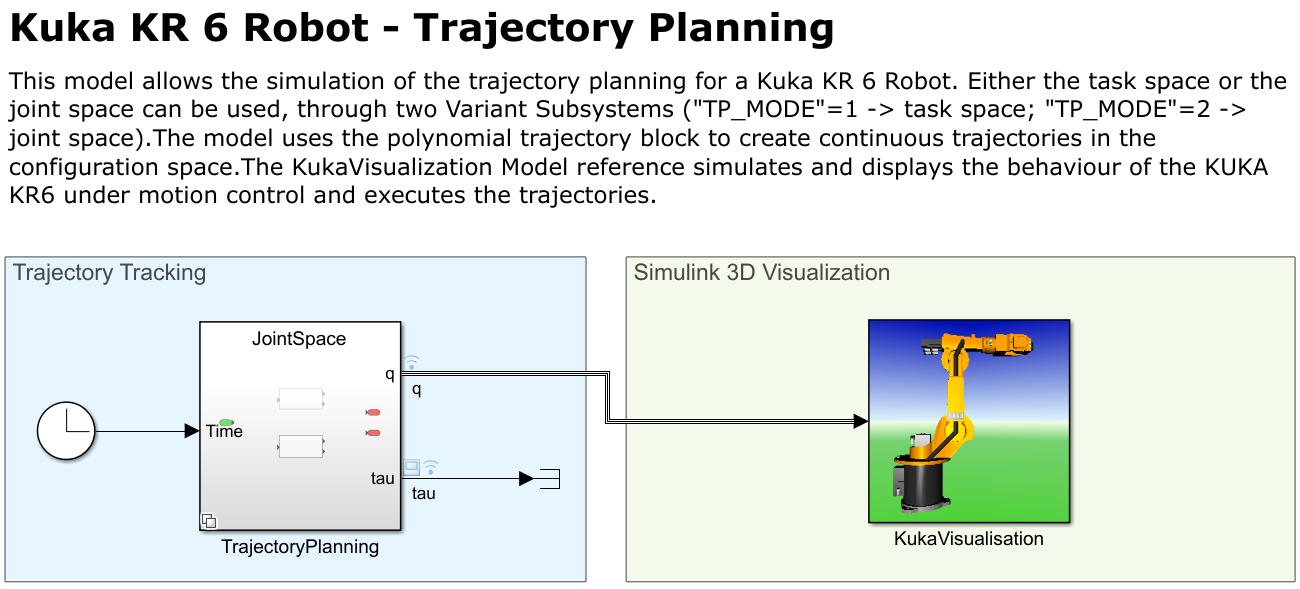

#### **lib_Solver **

The library lib_Solver contains the three blocks that are used in the Simulink model. Each block is a Matlab function that simply call the function described above.

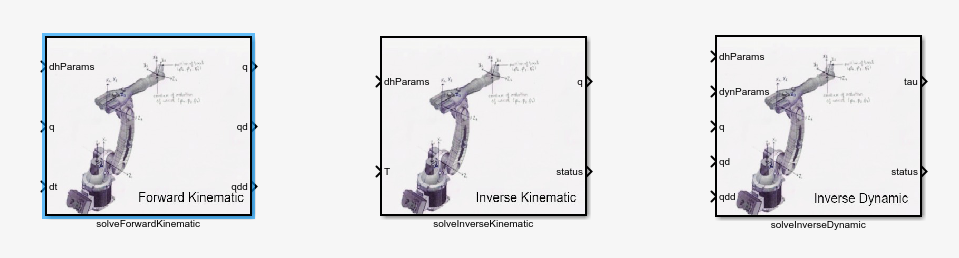

#### **Trajectory Generator System Object**

The object `core.trajectoryGenerator` [here] is responsible for the trajectory generation in the simulink model. The System Object implements a custom mask that allow the user to easily configure the desired trajectory:

- SolverSpace: whether `TaskSpace` or `JointSpace`. For the task space the orientation is not automatically integrated (the slerp method is not still tested and validated). For Joint space, the orientation is automatically integrated as soon as it is defined.

- Method: whether `Cubic` or `Quintic Polynomial`. If quintic is selected, the popup allow the user to select the desired acceleration, otherwise is hidden.

- Waypoints: the set of waypoints

- TimePoints: the set of time points associated to the waypoints.

- Velocity: the desired velocities, associated to the waypoints.

- Acceleration: the desired acceleration, associated to the waypoints (available only for quintic polynomial).

- IncludeOrientation/Orientations: if check the orientation at the waypoints can be defined (only in TaskSpace).

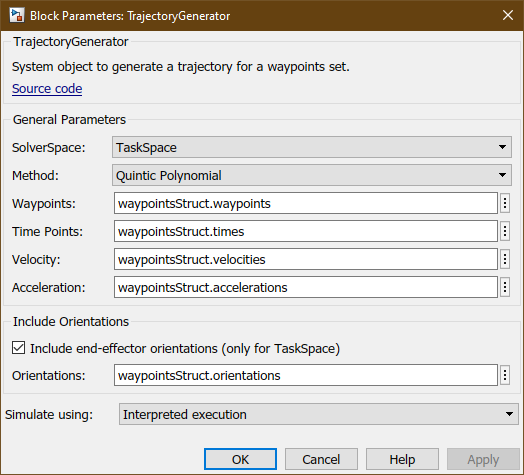

### TrajectoryPlanning Subsystem

Through the Variant subsystem is it possible to select in with space the simulate should be executed:

- `TP_MODE = 1 `for task space

- `TP_MODE = 2 `for joint space

#### TaskSpace Subsystem

#### 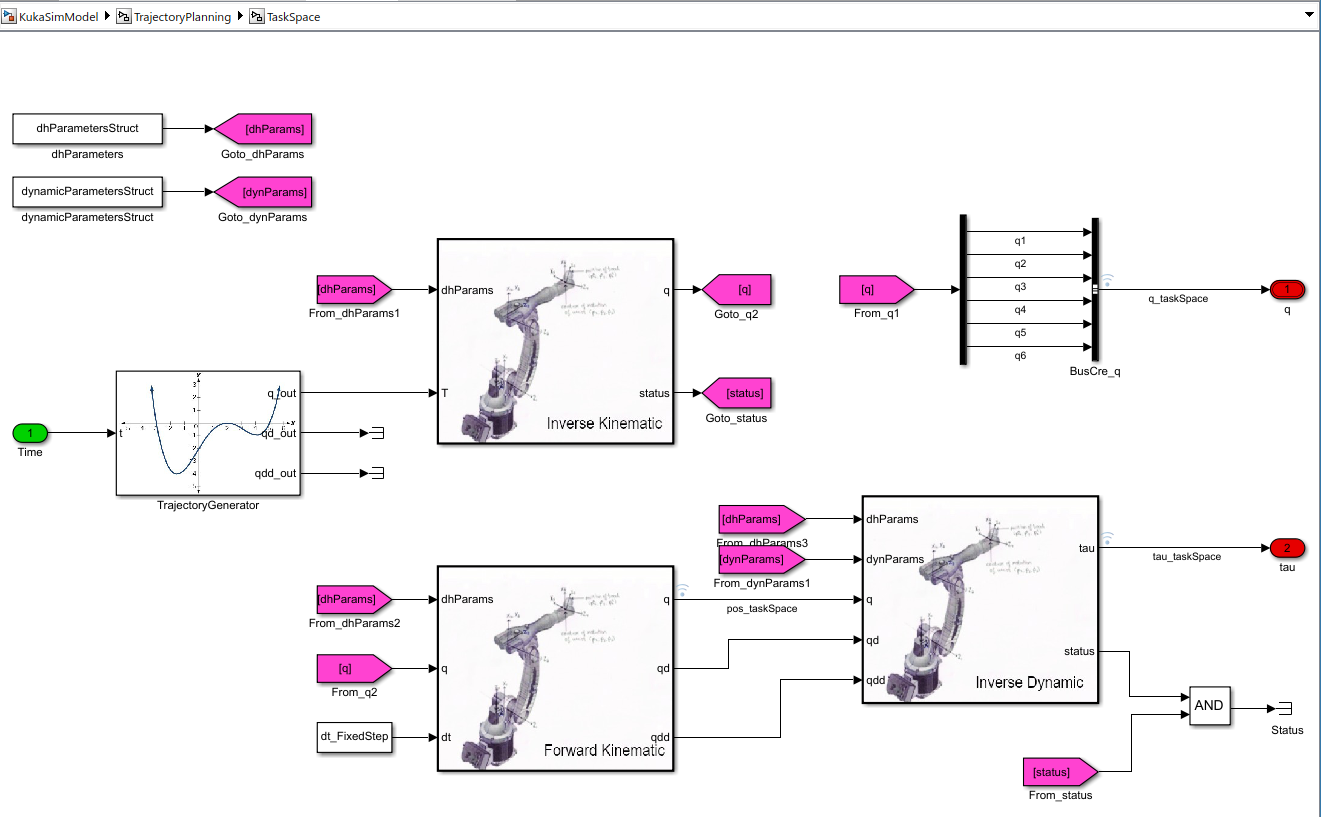

#### **JointSpace Subsystem**

### 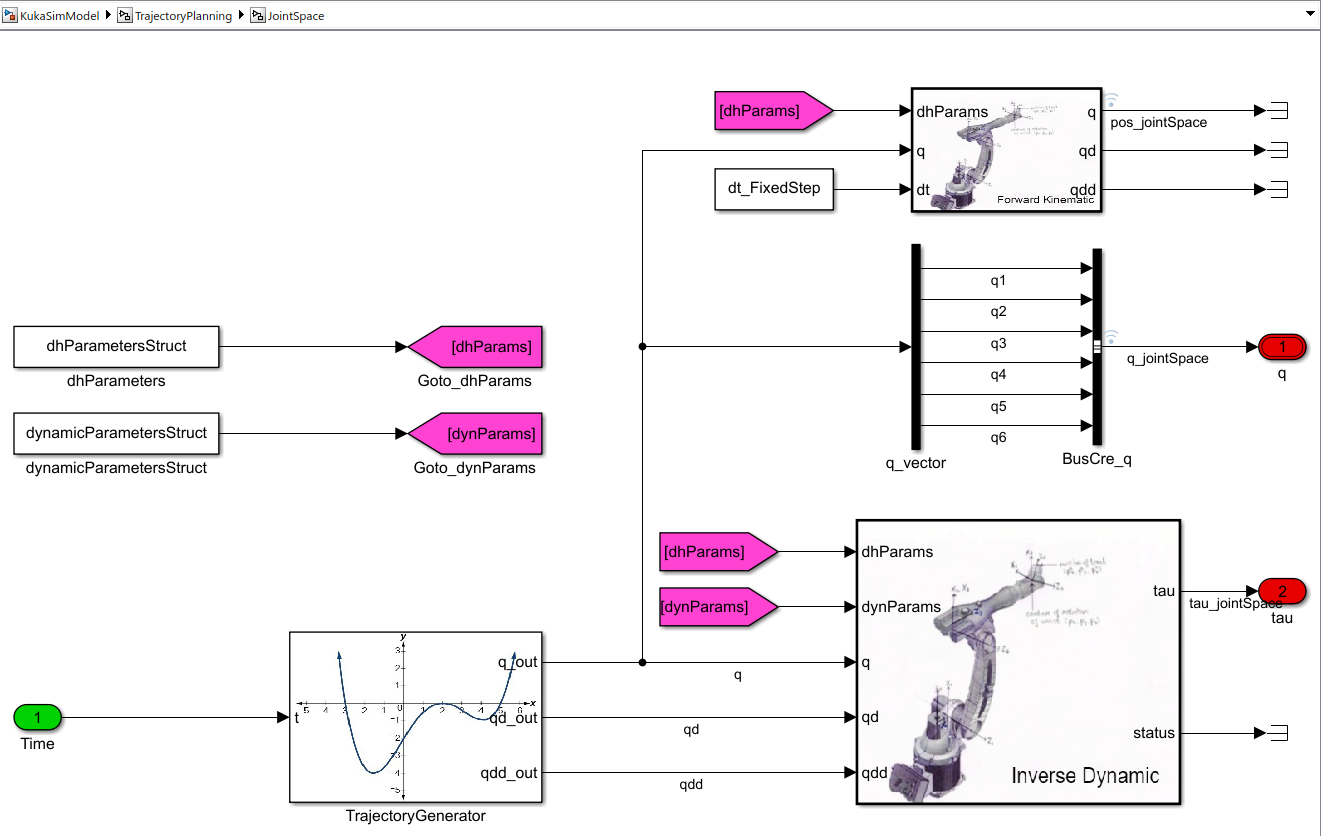

### KukaVisualization Subsystem

The KukaVisualization Subsystem set the calculated joint angles, for the wrl visualisation, using the Simulink 3D Animation toolbox.

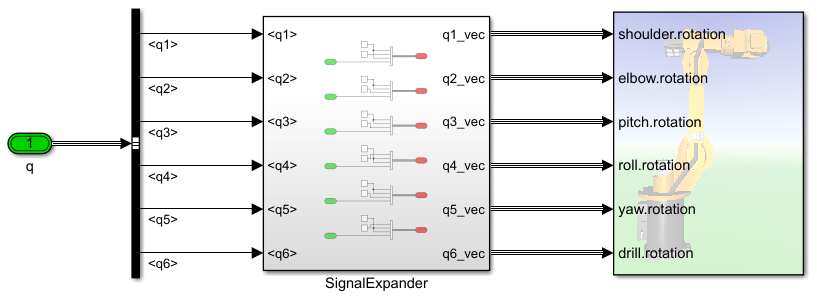

## **Simulation**

### **Run setup**

% Set configuration
clear config; % ensure clear config

config.space        = 2;
config.trajectory   = 2;
config.taskColor    = [.64 .02 .03];
config.jointColor   = [.02 .52 .51];
config.visualize    = false;

modelName = 'KukaSimModel';

% Startup setup
startup;

|    Startup KukaKR6...    |
-> Reloading D-H parameters...
     d       a      alpha     offset
    ____    ___    _______    ______

     675    350    -1.5708      0   
       0    850          0      0   
       0    145     1.5708      0   
    -820      0    -1.5708      0   
       0      0     1.5708      0   
    -170      0     3.1416      0   

-> Reloading Dynamic parameters...
Mass: 
    5.0000
    5.0000
    5.0000
    4.0885
    1.6154
    0.0160

-> Reloading Waypoints...
Computing home configuration...
Running gen_waypointSet_02...
-> Reloading Bus Objects...
-> Setting Variant Subsystem...
TP_MODE=2->["JointSpace"]
-> Loading model "KukaSimModel.slx"...
Setting "StopTime"=30s...
Initialization Done.



% initialize lastRun variable
lastRun = struct( ...
    'space', [], ...
    'trajectory', [], ...
    'waypoints', []);

### **Simulate TaskSpace**

disp('========================================');

disp('| Start simulation for "TaskSpace"...  |');

| Start simulation for "TaskSpace"...  |


disp('========================================');

config.space = 1;
TP_MODE = config.space;
if config.visualize
    open('KukaKR6.wrl');
end

% start simulation
[~, waypointsStruct] = enableFastRestartIfPossible(modelName, lastRun, config, eeHomeConfig);

Running gen_waypointSet_02...
[!] No previous run could be retrieved.
-> Compilation enabled. [FastRestart="off"]


disp(waypointsStruct.waypoints);

        1345         895         895        1395        1445        1445        1345
           0           0        -500         100         200        -100           0
        -315        -165         185         435        -765        -365        -315



simOutTask = sim(modelName);

Selected waypoint set: "gen_waypointSet_02".
[26-Sep-2021 13:50:59]: Start simulation...


[26-Sep-2021 13:51:27]: Stop simulation.



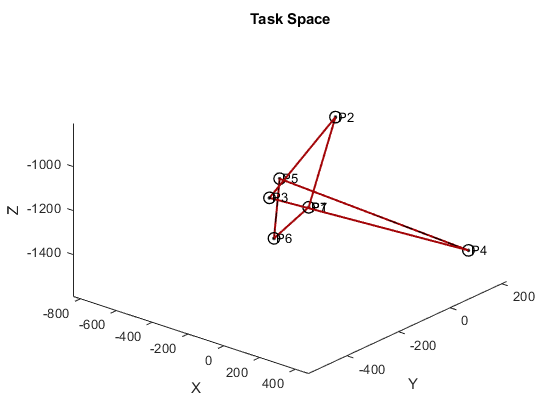


% get trajectory information
taskTrajectory = reshape(simOutTask.logsout.getElement('pos_taskSpace').Values.Data(:, 6, 1:end-1), ...
    3, numel(simOutTask.tout)-1);
% plot waypoints and trajectory
figure; hold on;
plotWaypoints(waypointsStruct.waypoints, taskTrajectory, config.taskColor);

title('Task Space');
view(40, 35);


lastRun = struct( ...
    'space', TP_MODE, ...
    'trajectory', config.trajectory, ...
    'waypoints', waypointsStruct);
disp('Done.');

Done.


### **Simulate JointSpace**

disp('========================================');

disp('| Start simulation for "JointSpace"... |');

| Start simulation for "JointSpace"... |


disp('========================================');

config.space = 2;
TP_MODE = config.space;
if config.visualize
    open('KukaKR6.wrl');
end
 
% start simulation
[~, waypointsStruct] = enableFastRestartIfPossible(modelName, lastRun, config, eeHomeConfig);

Running gen_waypointSet_02...
[!] Current Space ("2") differs from previous one ("1").
-> Compilation enabled. [FastRestart="off"]


disp(waypointsStruct.waypoints);

        1345         895         895        1395        1445        1445        1345
           0           0        -500         100         200        -100           0
        -315        -165         185         435        -765        -365        -315




warning off
simOutJoint = sim(modelName);

Selected waypoint set: "gen_waypointSet_02".
[26-Sep-2021 13:51:34]: Start simulation...
[26-Sep-2021 13:51:34]: Solve Inverse Kinematics in JointSpace...
[26-Sep-2021 13:52:04]: Stop simulation.



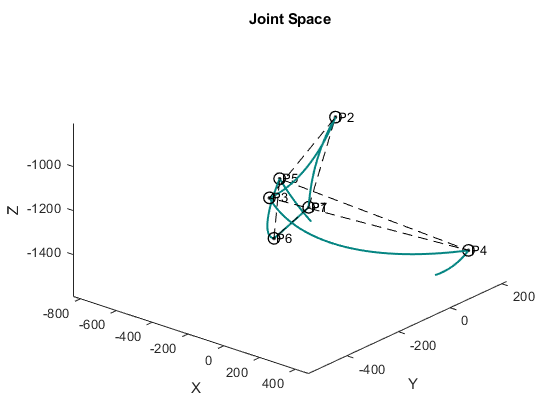

warning on

% get trajectory information
jointTrajectory = reshape(simOutJoint.logsout.getElement('pos_jointSpace').Values.Data(:, 6, 1:end-1), ...
    3, numel(simOutJoint.tout)-1);
% plot waypoints and trajectory
figure; hold on;
plotWaypoints(waypointsStruct.waypoints, jointTrajectory, config.jointColor);
title('Joint Space');
view(40, 35);


lastRun = struct( ...
    'space', TP_MODE, ...
    'trajectory', config.trajectory, ...
    'waypoints', waypointsStruct);
disp('Done.');

Done.


### Compare generated trajectories

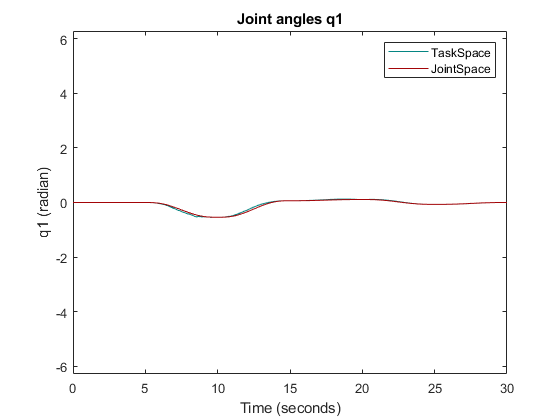

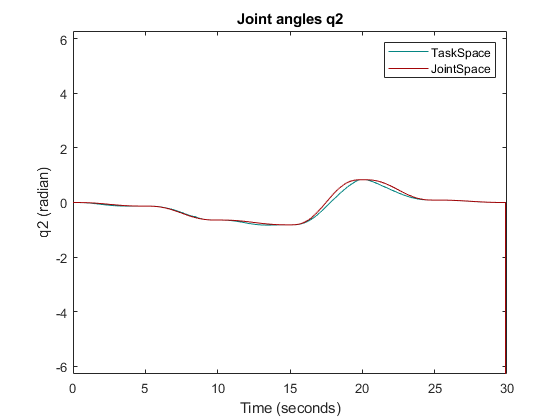

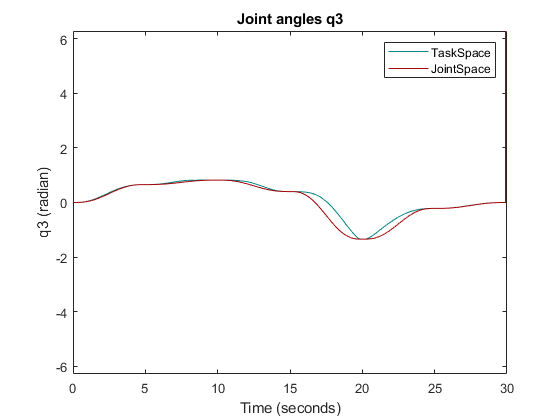

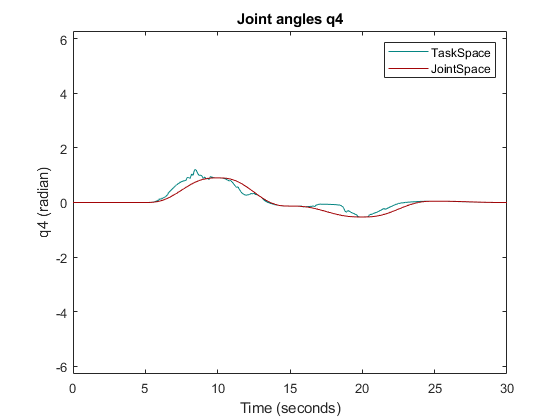

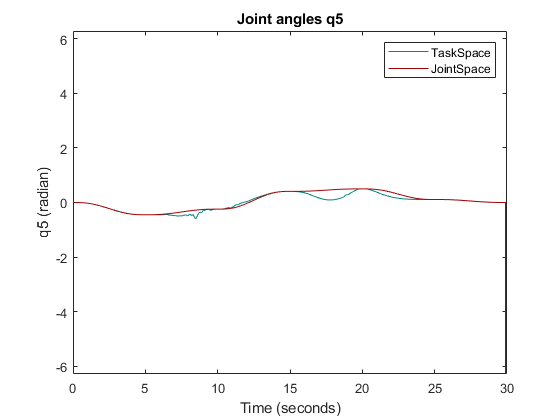

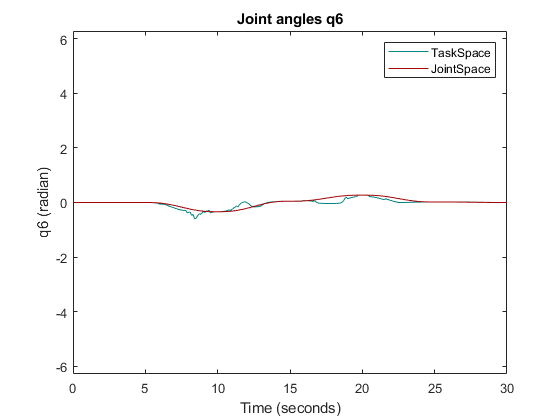

qTask = simOutTask.logsout.getElement('q').Values;
qJoint = simOutJoint.logsout.getElement('q').Values;
joints = fieldnames(qTask);
for i=1:numel(joints)
    figure;
    plot(qTask.(joints{i}), "Color", config.jointColor); hold on;
    plot(qJoint.(joints{i}), "Color", config.taskColor);
    ylim([-2*pi, 2*pi]);
    legend('TaskSpace', 'JointSpace');
    title(sprintf('Joint angles %s', joints{i}));
end

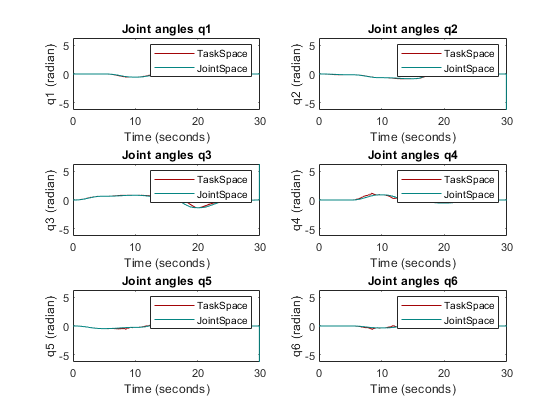


verticalAling = false;
figure; hold on;
for i=1:numel(joints)
    if verticalAling
        align = subplot(6, 1, i);
    else
        align = subplot(3, 2, i);
    end
    plot(qTask.(joints{i}), "Color", config.taskColor); hold on;
    plot(qJoint.(joints{i}), "Color", config.jointColor);
    ylim([-2*pi, 2*pi]);
    legend('TaskSpace', 'JointSpace');
    title(sprintf('Joint angles %s', joints{i}));
end

## Bibliography

[1] T. Sugihara, "Solvability-unconcerned inverse kinematics based on Levenberg-Marquardt method with robust damping," *2009 9th IEEE-RAS International Conference on Humanoid Robots*, 2009, pp. 555-560, doi: 10.1109/ICHR.2009.5379515.

[2] K. Ofjall and M. Felsberg,  "Rapid explorative direct inverse kinematics learning of relevant locations for active vision," in *2013 IEEE Workshop on Robot Vision (WORV 2013)*, Clearwater Beach, FL, 2013 pp. 14-19. doi: 10.1109/WORV.2013.6521932

[3] [https://people.duke.edu/~hpgavin/ce281/lm.pdf](https://people.duke.edu/~hpgavin/ce281/lm.pdf)

[4] [https://modernrobotics.northwestern.edu/nu-gm-book-resource/8-3-newton-euler-inverse-dynamics/](https://modernrobotics.northwestern.edu/nu-gm-book-resource/8-3-newton-euler-inverse-dynamics/)

[5] Roy, F., "Inverse Dynamics - The Recursive Newton-Euler Method.", Springer US, 1987, pp. 65-77, doi: 10.1007/978-0-387-74315-8_4

function [fastRestart, waypointsStruct] = enableFastRestartIfPossible(modelName, lastRun, config, homeConfig)
setFastRestart = @(m, u) set_param(m, 'FastRestart', u);
isTrajectoryEqual = isequal(lastRun.trajectory, config.trajectory);
isSpaceEqual = isequal(lastRun.space, config.space);
waypointsStruct = loadWaypoints(config.trajectory, homeConfig);
isWaypointSetEqual = isequal(waypointsStruct, lastRun.waypoints);
fastRestart = isTrajectoryEqual && isSpaceEqual && isWaypointSetEqual;

if fastRestart
    fprintf(['Configuration did not change from previous run.\n' ...
        '-> Compilation skipped: [FastRestart="on"]\n']);
    setFastRestart(modelName, 'on');
    return;
end
if isempty(lastRun.trajectory) || isempty(lastRun.space) || isempty(lastRun.waypoints)
    fprintf('[!] No previous run could be retrieved.\n');
else
    if ~isTrajectoryEqual
        fprintf('[!] Current Trajectory ("%d") differs from previous one ("%d").\n', config.trajectory, lastRun.trajectory);
    end
    if ~isSpaceEqual
        fprintf('[!] Current Space ("%d") differs from previous one ("%d").\n', config.space, lastRun.space);
    end
    if ~isWaypointSetEqual
        fprintf('[!] Current WaypointSet differs from previous one.\n');
        if numel(waypointsStruct.times) ~= numel(lastRun.waypoints.times)
            fprintf('[!] Update stop time (number of waypoint differs from previous run %d~=%d)... \n', ...
                numel(waypointsStruct.times), numel(lastRun.waypoints.times));
            set_param('KukaSimModel', 'StopTime', num2str(max(waypointsStruct.times)));
        end
    end
end
fprintf('-> Compilation enabled. [FastRestart="off"]\n');
setFastRestart(modelName, 'off');
end